# Calculation of the U* index 

This code is used to calculate the U* index for a plate in membrane action under a point load on its corner.

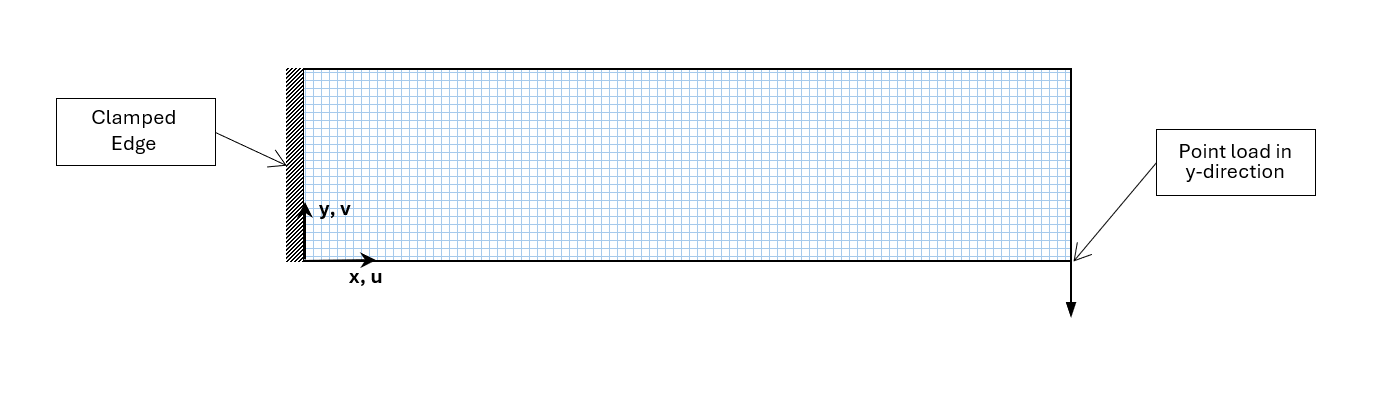

clc;
clear;

## Setting up the static problem:

Importing the geometry:

geom = importGeometry("Geometry.stl"); 

Visualization of the geometry:

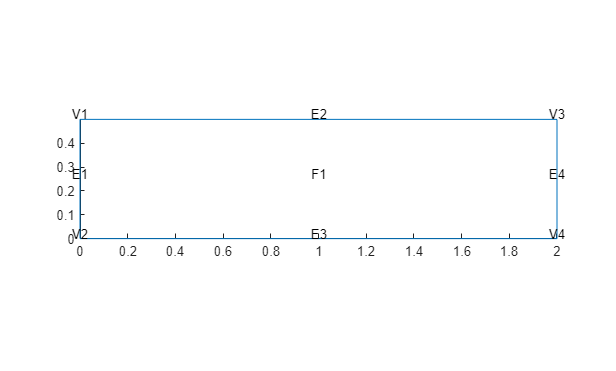

pdegplot(geom, EdgeLabel="on", VertexLabel="on", FaceLabel="on");

Initialization of the FEM model:

model = femodel(AnalysisType="structuralStatic", Geometry=geom);
model.PlanarType = "planeStress";

Setting the material properties:

model.MaterialProperties = materialProperties("YoungsModulus",33E9,"PoissonsRatio",0.2);

Setting the boundary conditions:

model.EdgeBC(1) = edgeBC(XDisplacement=0, YDisplacement=0);

Setting the loading conditions:

model.VertexLoad(4) = vertexLoad(Force=[-100000;-100000]);

Generation of the mesh and retrieving the coordinates of the nodes:

model = generateMesh(model, "GeometricOrder", "linear", "Hmax", 0.04, "Hmin", 0.005); 
mesh = model.Geometry.Mesh;
nodes = mesh.Nodes';

Visualization of the mesh:

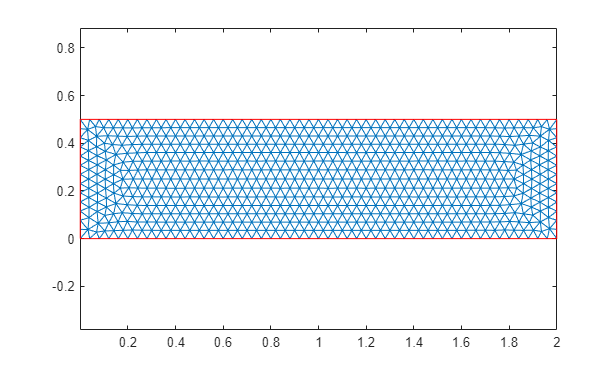

pdemesh(mesh);

Assembling the matrices needed for the FEM analysis and retrieving the stiffness matrix and applied loading:

mtces = assembleFEMatrices(model);
Kmtx = full(mtces.K);
K = zeros(size(Kmtx));
K(1:2:end,1:2:end) = Kmtx(1:width(Kmtx)/2,1:width(Kmtx)/2);
K(2:2:end,1:2:end) = Kmtx(width(Kmtx)/2+1:end,1:width(Kmtx)/2);
K(1:2:end,2:2:end) = Kmtx(1:width(Kmtx)/2,width(Kmtx)/2+1:end);
K(2:2:end,2:2:end) = Kmtx(width(Kmtx)/2+1:end,width(Kmtx)/2+1:end);

Fmtx = full(mtces.G);
F = zeros(size(Fmtx));
F(1:2:end,1) = Fmtx(1:height(Fmtx)/2,1);
F(2:2:end,1) = Fmtx((height(Fmtx)/2)+1:end,1);
% spy(Kmtx)
% spy(K)

## Solving the system and retrieving the displacements:

R = solve(model);
disp = R.Displacement;
dispX = disp.ux;
dispY = disp.uy;

u = zeros(2*length(dispX),1);
u(1:2:end) = dispX;
u(2:2:end) = dispY;

Visualization of the displacements:

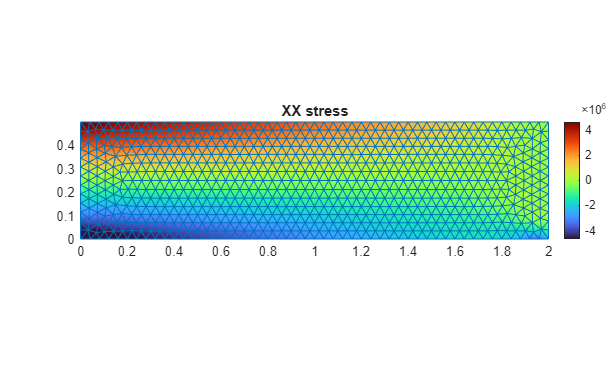

% Data to visualize
meshData = R.Mesh;
nodalData = R.Stress.sxx;
deformationData = R.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,nodalData, ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",0, ...
    "MeshVisible",true, ...
    "Title","XX stress", ...
    "ColorLimits",[-4678000 4661000]);


% Clear temporary variables
clearvars meshData nodalData deformationData

Retrieving the load, support, and free nodes: 

numNodes = length(nodes(:,1));

LoadNodes = sort(findNodes(mesh, "region", "Vertex",4))';
SupportNodes = sort(findNodes(mesh, "region", "Edge",1))';
SupportAndLoadNodes_Ordered = sort([LoadNodes; SupportNodes]);

FreeNodes = (1:numNodes)';
FreeNodes(SupportAndLoadNodes_Ordered) = [];

Getting the DOFs for the load and support nodes:

numDOFs = 2*numNodes;

DOFsLoadNodes = zeros(2*length(LoadNodes),1);
DOFsLoadNodes(2:2:2*length(LoadNodes)) = 2*LoadNodes;
DOFsLoadNodes(1:2:end) = 2*LoadNodes-1;

DOFsSupportNodes = zeros(2*length(SupportNodes),1);
DOFsSupportNodes(2:2:end) = 2*SupportNodes;
DOFsSupportNodes(1:2:end) = 2*SupportNodes-1;

DOFsSupportAndLoadNodes_Ordered = sort([DOFsLoadNodes; DOFsSupportNodes]);

DOFsFreeNodes = 1:2*numNodes;
DOFsFreeNodes(DOFsSupportAndLoadNodes_Ordered) = [];
DOFsFreeNodes = DOFsFreeNodes';

## Load Path Calculation

Calculating U for the original system:

U_index_total = (1/2)*transpose(K*u)*u;

Initializing the vectors for U’ and the U* index:

U_free_nodes = zeros(numNodes,1);
U_index = zeros(numNodes,1);

Looping over all the nodes:

for kk = 1:numNodes
    fixedNodeDOF1 = (kk)*2-1;

Analyzing whether the node in each iteration is a support or a load node:

    if ~ismember(fixedNodeDOF1,DOFsSupportAndLoadNodes_Ordered) && ~ismember(fixedNodeDOF1+1,DOFsSupportAndLoadNodes_Ordered)

Ordering the degrees of freedom (DOFs):

        DOFsKnown_Ordered = sort([DOFsSupportAndLoadNodes_Ordered; fixedNodeDOF1; fixedNodeDOF1+1]);
        uFixedNode = u;
        uFixedNode(fixedNodeDOF1:fixedNodeDOF1+1,1) = 0;
        uKnown = uFixedNode(DOFsKnown_Ordered);

Applying the known displacements and solving for the remaining ones:

        F_known_displ = K(DOFsKnown_Ordered,DOFsKnown_Ordered)*uKnown;
        DOFsUnknown = (1:numDOFs)';
        DOFsUnknown(DOFsKnown_Ordered) = [];
        K_fixed_node = K;
        K_fixed_node(DOFsKnown_Ordered,:) = [];
        K_unknown_displ = K_fixed_node(:, DOFsKnown_Ordered);
        F_unknown_displ = -1*(K_unknown_displ * uKnown);
        K_fixed_node(:,DOFsKnown_Ordered) = [];
        uUnknown = K_fixed_node\F_unknown_displ;

Assembling the displacements back into one vector:

        u_fixed_node = zeros(numDOFs,1);
        u_fixed_node(DOFsKnown_Ordered) = uKnown;
        u_fixed_node(DOFsUnknown) = uUnknown;

Calculating the values of U’ and U* index for the node:

        U_free_nodes(kk,1) = (1/2)*transpose(K*u_fixed_node)*u_fixed_node;
        U_index(kk,1) = 1 - U_index_total/U_free_nodes(kk);
    end
end

Assigning the U* index value of one to the load nodes:

U_index(LoadNodes) = 1;

## Visualization of the load path

### Plotting the contour of the U* index field:

XNodesPlot = nodes(:,1);
YNodesPlot = nodes(:,2);

Interpolating the values of the U* index field over a unfirom field:

[X,Y]=meshgrid(linspace(min(XNodesPlot),max(XNodesPlot),300),linspace(min(YNodesPlot),max(YNodesPlot),100));
zq = griddata(XNodesPlot, YNodesPlot, U_index, X,Y,'cubic');

Plotting the contour of the field:

figure;
[C, hCont] = contourf(X,Y,zq,'linecolor','black','LineWidth',0.01,"ShowText","on","LabelSpacing",600);
daspect([2 2 2])
hold on

Finding the gradients of the field in the x- and y-directions:

[UX_zq, UY_zq] = gradient(zq);

Setting the starting points of the streamlines:

XSupportNodes = nodes(SupportNodes,1);
YSupportNodes = nodes(SupportNodes,2);
[startX,startY] = meshgrid(XSupportNodes,YSupportNodes);

Plotting the load paths:

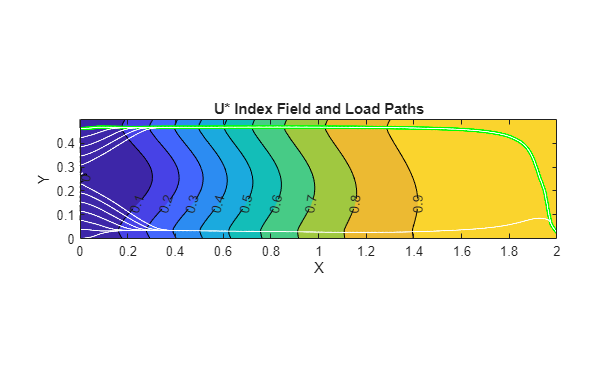

lineobj = stream2(X, Y,UX_zq,UY_zq,startX,startY);
lineobj = streamline(lineobj);
for i = 1:length(lineobj)
    lineobj(i).Color = "black";
    lineobj(i).LineWidth = 1.5;
end

title('U* Index Field and Load Paths');
xlabel('X');
ylabel('Y');
hold off

## Getting the variation of the U* index along the load path:

Retrieving the coordinates of the upper load path:

C31 = [transpose(lineobj(31).XData), transpose(lineobj(31).YData)];

Initializing the vectors for the variation of the U* index:

numNodes_C31 = height(C31);
Nodes_C31 = zeros(numNodes_C31,3); %including the node's ID
U_C31 = zeros(numNodes_C31,1);

Finding the U* index values along the load path:

for i = 1:numNodes_C31

Retrieving the x and y coordinates of a point along the load path:

    C31_coord = [C31(i,1), C31(i,2)];

Finding the index of the closest node to this point in the mesh

    [~, indx] = min(transpose(pdist2(C31_coord,nodes)));

Storing the index and the coordinates of the closest node:

    Nodes_C31(i,1) = indx;
    Nodes_C31(i,2:3) = nodes(indx,:);

 Retrieving the U* value of the closest node: 

    U_C31(i) = U_index(indx);
end 

Calculating the total length of the upper load path along with the length to each point on the path:

C31_length = 0;
C31_s = zeros(numNodes_C31,1);
for i = 1:numNodes_C31-1 
    C31_length = C31_length + sqrt( (C31(i+1,1)-C31(i,1))^2 + (C31(i+1,2)-C31(i,2))^2 );
    C31_s(i+1) = C31_length;
end

Plotting the variation of the U* index along the load path:

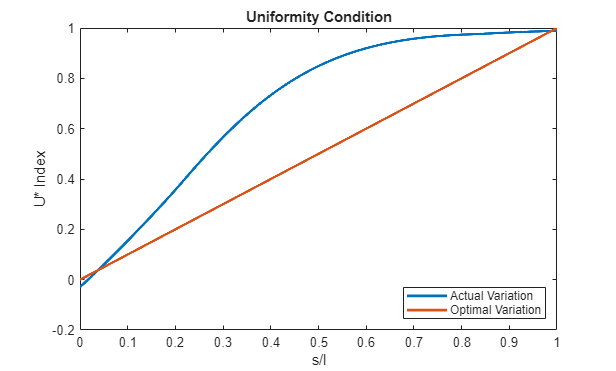

figure;
plot(C31_s/C31_length,smoothdata(U_C31,"loess"),LineWidth=2)
hold on
x = 0:1/numNodes_C31:1;
y = x;
plot(x,y,LineWidth=2)
title("Uniformity Condition")
xlabel("s/l")
ylabel("U* Index")
legend('Actual Variation','Optimal Variation',Location='southeast')
hold off

## Streamlines of the U* index field:

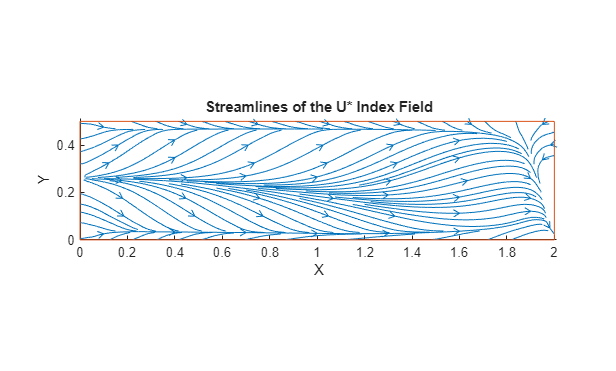

figure;
[sliceverts, sliceaverts] = streamslice(X, Y,UX_zq,UY_zq);
slicelinobj = streamslice(X, Y,UX_zq,UY_zq);
hold on
pdegplot(geom)
title("Streamlines of the U* Index Field")
xlabel("X")
ylabel("Y")

## References:

K. Marhadi and S. Venkataraman, “Comparison of Quantitative and Qualitative Information Provided by Different Structural Load Path Definitions,” *International Journal for Simulation and Multidisciplinary Design Optimization*, vol. 3, pp. 384–400, Jul. 2009, doi: [10.1051/ijsmdo/2009014](https://doi.org/10.1051/ijsmdo/2009014). 